# Cálculo

Este subcapítulo en el libro guía está algo desactualizado, por ende, se tomará la información de la documentación de **Symbolic Math Toolbox**. El enlace a esta documentación se encuentra al final del subcapítulo anterior (**sc3**).

## Límites: función `limit`

La función permite calcular el límite utilizando la definición de este.

Sea la función $f(x) = \cos(x)$, la derivada de esta función mediante la definición es


$$f'(x)=\lim_{h\rightarrow 0} \frac{\cos(x+h)-\cos(x)}{h}=-\sin(x)$$


Ahora, utilizando MATLAB podemos replicar el mismo resultado.

clear

syms x h
limit((cos(x+h)-cos(x))/h,h,0)

Recapitulando tenemos que ingresar:

- Primero el límite.

- Luego la variable de variación (en algunos textos en lugar de $h$ le llaman $\Delta x$).

- Finalmente, hacia qué número es la tendencia.

Recordemos que MATLAB permite ingresar una representación de infinito `Inf`, por ende, también es posible ingresar límites con tendencia hacia el infinito positivo o negativo.

### Límites laterales

Recordemos que existen límites que son divergentes, es decir, el límite por la derecha es diferente del límite por la derecha (hablando del Cáluclo en una Variable). También es posible estudiar estos límites con MATLAB.

Sea la función $g(x)=\frac{x}{|x|}$ , entonces analizando los límites tenemos:

limit(x/abs(x),x,0,"left")      % Límite por la izquierda.
limit(x/abs(x),x,0,"right")     % Límite por la derecha.

### Tabla resumen de límites con MATLAB

En la siguiente tabla se observa las funciones para límites y el detalle de cómo usarlas.

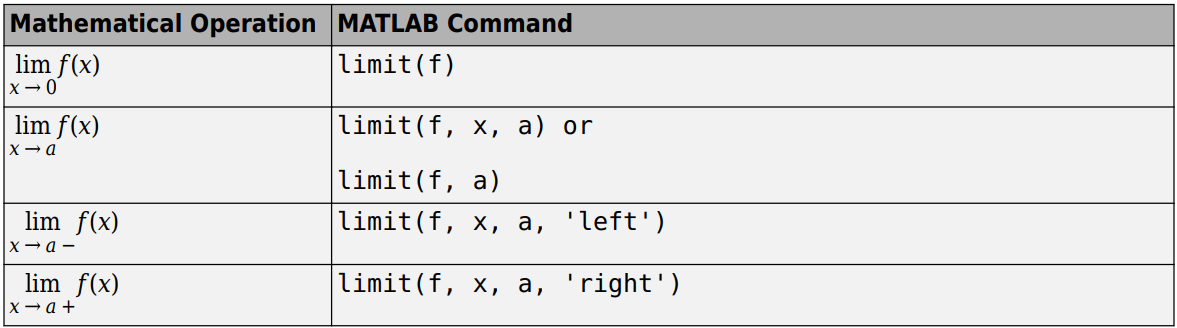

## Diferenciación: función `diff`

La función `diff` permite difereciar (derivar) una expresión simbólica.

clear

syms x
f = sin(5*x)    % Función f.
y1 = diff(f)    % Derivada de f.

Se debe recordar que para nombrar variables sólo se puede utilizar letras, números y guión bajo. Por lo tanto, no es posible nombrar a una variable `f'`.

En cambio, si se desea diferenciar y evaluar a la vez se pueden utilizar las funciones `subs` y `vpa` de forma aninada.

g = exp(x)*cos(x)   % Función g.
y2 = diff(g)        % Derivada de g.

subs(y2,x,2)        % Reemplazando x=2 en la derivada de g.
vpa(subs(y2,x,2))   % Mejor visualización del reemplazo anterior.

Se hace hincapié una vez más (dentro de este capitulo) que para realizar cálculos con los resultados se deben convertir de simbólicos a numéricos.

Para derivar una constate se debe definirla previamente la constante como una expresión simbólica, caso contrario devolverá la fución `diff` una matriz vacía.

c = sym('5')    % Función constante c.

diff(c)         % Derivada de c.

diff(5)         % Derivada de 5 (no se ha definido como expresión simbólica).

### Derivada *n*-ésima (o de orden superior)

Existen dos formas de encontrar una derivada de orden superior: anidar varias funciones `diff` o ingresar un segundo argumento a esta.

Por ejemplo, utilizando la función $g$ definida anteriormente podemos encontrar su segunda derivada.

diff(diff(g))   % Segunda derivada con funciones anidadas.

diff(g,2)       % Segunda derivada ingresando un segundo argumento a la función (n=2).

### Derivadas parciales

Evidentemente también es posible determinar la derivada parcial de una función de dos o más variables.

clear

syms s t
f = sin(s*t)    % Función f que depende de s y t.

diff(f,s)       % Derivada parcial respecto de s.
diff(f,t)       % Derivada parcial respecto de t.

Si no se especifica la variable respecto a la que derivar, MATLAB tomará la más cercana a **x** (porque **x** es la variable de derivación por defecto).

#### Función `symvar`

La función `symvar` permite visualizar respecto a qué variable derivará la función `diff` (cuando hay más de una variable, por supuesto).

symvar(f,1)     % La primera variable más cercana a x.

### Derivadas parciales de orden superior

Básicamente deberemos de especificar en la función `diff` la expresión, la variable de derivación y el orden de la derivada.

diff(f,t,2)     % Segunda derivada de f respecto de t.

Claro que si se hubiera ingresado

diff(f,2)

se obtiene el mismo resultado dado que **t** es la variable más cercana a **x**.

### Tabla de resumen de diferenciación con MATLAB

La siguiente tabla resume cómo diferenciar en MATLAB. Además incluye la función `jacobian` que permite obtener la jacobiana de una matriz, sin embargo, como este tema es de Cálculo Avanzado no se hicieron ejemplos.

No obstante, consultando en la documentación se la puede entender de mejor manera.

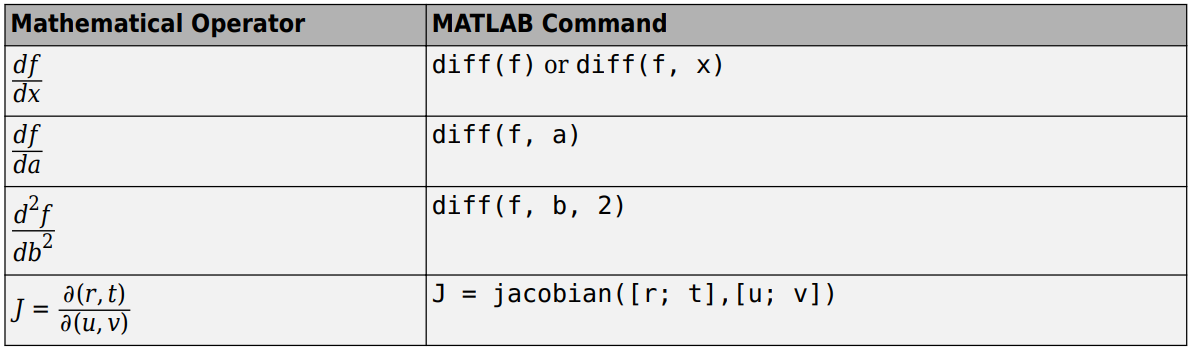

## Integración: función `int`

La integración es el proceso contrario a la diferenciación. En realidad, por uno de los teoremas fundamentales del Cálculo se sabe que la derivada y la integral son funciones inversas.

Así pues, para encontrar la integral de una función dada se utiliza la función `int`.

**Nota:** En otros lenguajes de programación la función `int` define números enteros (**int**eger), sin embargo, en capítulos anteriores se estudiaron las formas en que MATLAB define los tipos de datos numéricos. Por ende, no se debe confundir la función `int` que sirve para integrar en MATLAB con la función `int` de otros lenguajes.

### Integral indefinida

Para integrales indefinidas MATLAB devuelve una única función, es decir, sin la constante de integración. Recordemos que la función obtenida mediante una integral es una familia de funciones en realidad.

Sea la siguiente integra indefinida


$$\int \cos(at+b)dt$$


podemos deteminarla utilizando MATLAB.

clear

syms a b t
g = cos(a*t + b)

int(g)

Únicamente debemos recordar que en realidad no es una función, como ya se mencionó, si no una familia de funciones, pero MATLAB no añade la constante de integración al resultado.

**Nota:** Las mismas consideraciones respecto a la variable de diferenciación se aplican a la variable de integración.

### Integral definida

Sea la siguiente integral definida


$$\int_0 ^{\pi/2} \sin(2x)dx$$


podemos determinarla utilizando MATLAB.

clear

syms x
f = sin(2*x)

int(f,0,pi/2)

### Tabla resumen de integrales con MATLAB

La siguiente tabla enumera ejemplos donde se puede observar cómo obtener una derivada definida o indefinida.

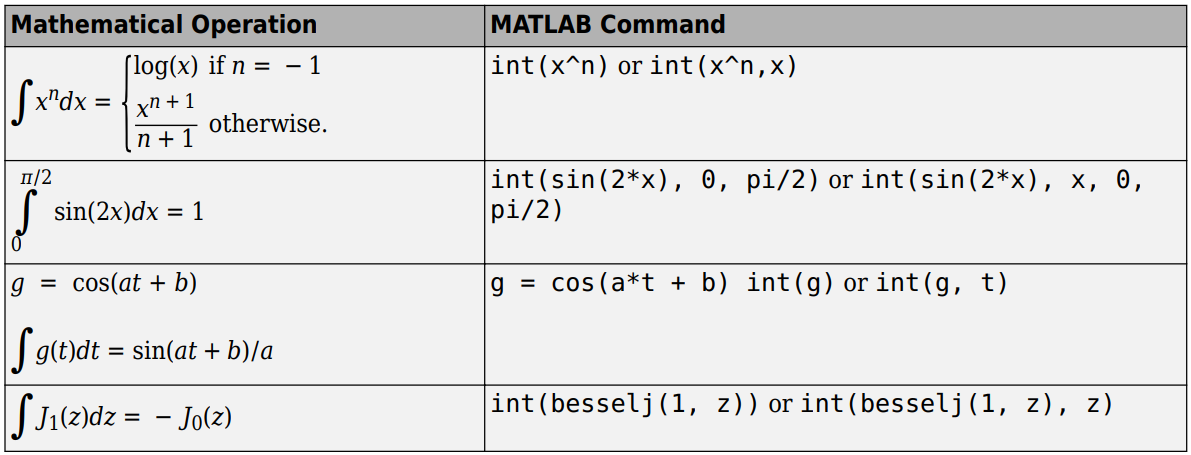

### Aclaración acerca de las integrales en MATLAB

Se debe recordar que no toda función es integrable, o al menos no tiene una versión corta de sí. Algunas antiderivadas suelen ser extensas. En estos casos es posible que MATLAB no pueda determinarlas o devuelva una función que tenga la expresión `erf` que signica función errónea (*error function*).

Además, también existen integrales impropias que tienen un tratamiento especial. Por ende, a diferencia del cálculo diferencial, el cálculo integral puede ser limitado en MATLAB.

# Ecuaciones diferenciales

El tema de ecuaciones diferenciales es demasiado amplio para cubrirlo en este repositorio, siquiera para hacer un resumen. Por ende, aquí se incluirá lo exclusivamente fundametal de las ecuaciones diferenciales.

Para conocer todo lo que se puede realizar con MATLAB sobre este tema se recomienda sobremanera revisar la documentación.

## Ecuación diferencial ordinaria de primer orden: función `dsolve`

Lo primero que se debe hacer es definir la ecuación diferencial. Una vez definida la ecuación se puede utilizar la función `dsolve` tanto para una solución sin condiciones de frontera como con ellas.

### Sin condiciones de frontera

Sea la ecuación diferencial


$$\frac{dy}{dt}=ty$$


podemos solucionarla utilizando MATLAB.

clear

syms y(t)
ode = diff(y,t) == t*y  % Se define la ecuación diferencial.

ySol(t) = dsolve(ode)      % Se encuentra la solución sin condiciones de frontera.

### Con condiciones de frontera

Además de definir la ecuación diferencial se definen las condiciones de frontera.

Sea la condición de frontera de la anterior ecuación diferencial


$$y(0)=2$$


entonces tenemos:

cond = y(0) == 2;               % Se definen las condiciones de frontera.
ySol(t) = dsolve(ode,cond)         % Se encuentra la solución con condiciones de frontera.

**Nota:** Si la ecuación diferencial es muy compleja, a pesar de ser ordinaria de primer orden, se puede intentar solucionarla numéricamente. Consultar la documentación para más detalles.

### Tabla resumen de ecuaciones diferenciales ordinarias

En la siguiente tabla se muestran algunos ejemplos para visualizar cómo funciona la función `dsolve` para resolver ecuaciones diferenciales ordinarias.

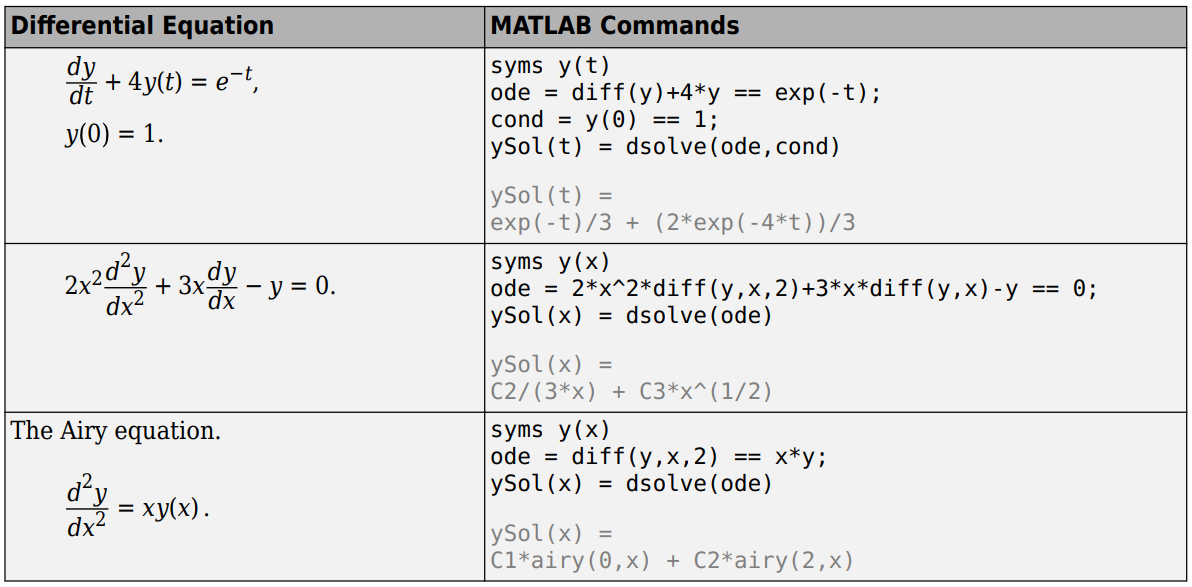

**Nota:** Si se require más detalles para solucionar ecuaciones diferenciales de segundo, tercer, n-ésimo orden; se puede consultar la documentación para conocer cómo hacerlo con MATLAB.

## Ecuaciones diferenciales no lineales con condiciones de frontera

También es posible solucionar este tipo de ecuaciones utilizando MATLAB, sin embargo, esta ecuación puede tener múltiples soluciones.

Sea la ecuación diferencial con su condición de frontera


$$\left(\frac{dy}{dt}+y\right)^2 =1$$



$$y(0)=0$$


entonces tenemos:

clear

syms y(t)
ode = (diff(y,t) + y)^2 == 1
cond = y(0) == 0

ySol(t) = dsolve(ode,cond)

En este caso, la ecuación diferencial posee dos soluciones.

## Sistemas de ecuaciones lineales

Utilizando la misma función `dsolve` ya estudiada es posible resolver sistemas de ecuaciones diferenciales con o sin condiciones de frontera.

Básicamente lo que se harán es crear arreglos de ecuaciones diferenciales y sus respectivas condiciones (si es que las tienen) para utilizar la función `dsolve`.

### Sin condiciones de frontera

Sean las ecuaciones diferenciales


$$\frac{du}{dt}=3u+4v\\
\frac{dv}{dt}=-4u+3v$$


entonces tenemos:

clear

syms u(t) v(t)
ode1 = diff(u) == 3*u + 4*v;    % Ecuación diferencial 1.
ode2 = diff(v) == -4*u + 3*v;   % Ecuación diferencial 2.
odes = [ode1; ode2]         % Sistema de ecuaciones diferenciales.

S = dsolve(odes)            % Solución del sistema de ecuaciones diferenciales
                            % sin condiciones de frontera.

Observe que `S` es un arreglo estructura (estudiando en capítulos anteriores). Esta estructura ha creado un campo para cada variable con el nombre de estas.

Por lo tanto, podemos acceder a las soluciones mediante estos campos.

S.u
S.v

Sin embargo, se puede crear un arreglo salida para asignar directamente una variable a cada solución.

[uSol(t), vSol(t)] = dsolve(odes)

### Con condiciones de frontera

Una vez tenemos el sistema de ecuaciones diferenciales, únicamente creamos otro con las condiciones de frontera para ingresar como segundo argumento en la función `dsolve`.

Sean las condiciones de frontera del anterior sistema


$$u(0)=0\\
v(0)=1$$


entonces tenemos:

cond1 = u(0) == 0;          % Condición 1.
cond2 = v(0) == 1;          % Condición 2.
conds = [cond1; cond2]      % Sistema de condiciones de frontera.

[uSol(t), vSol(t)] = dsolve(odes,conds) % Solución del sistema de ecuaciones diferenciales
                                        % con condiciones de frontera.

Para una mejor visualización podemos graficar las soluciones.

fplot(uSol)
hold on
fplot(vSol)
grid on
legend('uSol','vSol','Location','best')
% Para una mejor visualización se recomienda compilar este bloque de código
% en la ventana de comandos.